# Test PenguinPi web API

url = "http://10.0.0.20";
robot = PiBot(url)

robot =   PiBot with properties:

    url: "http://10.0.0.20:8080"


## Test ADC

robot.getVoltage()

ans = 7.1617

robot.getCurrent()

ans = 0.4235

## Test LEDs

for i=2:4
    robot.setLed(i, 1);
    pause(0.5)
    robot.setLed(i, 0);
end

for i=2:4
    robot.pulseLed(i, 0.1);
    pause(0.5)
end


## Test HAT

robot.getDIP()

ans = '80'

robot.getButton()

ans = '0'

for i=0:15
    robot.setLedArray(2^i);
end
robot.setLedArray(0);

for i=0:6
    robot.setLedArray(i);
    pause(1)
end
robot.setLedArray(0);

## Robot

### Test move

stat1 = robot.setVelocity(20, -20)

stat1 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


pause(2)
stat2 = robot.stop()

stat2 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]



pause(2)

stat1 = robot.setVelocity([20, -20])

stat1 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


pause(2)
stat2 = robot.stop()

stat2 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


### Test move with time

stat1 = robot.setVelocity([20, -20], 2)

stat1 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


pause(2)

### Test move with time and acceleration

stat1 = robot.setVelocity([20, -20], 2, 0.5)

stat1 = struct with fields:
       pose: [1×1 struct]
    encoder: [1×1 struct]


pause(2)

print_json(json1, json2)

Undefined function or variable 'json1'.

## Camera

img = robot.getImage();
about img

img [uint8] : 240x320x3 (230.4 kB)


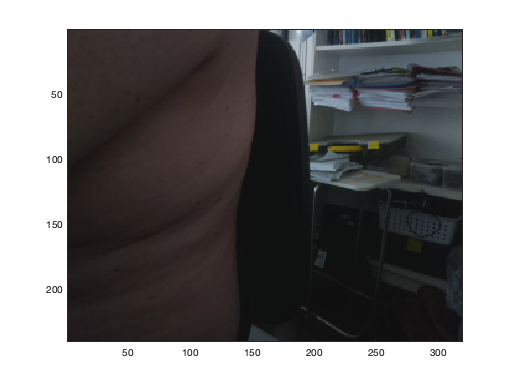

image(img)